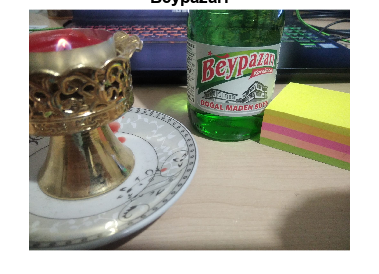

% BİR GÖRÜNTÜ ALMA
Bey = imread('Beypazari.jpg');
imshow(Bey);
title('Beypazarı')

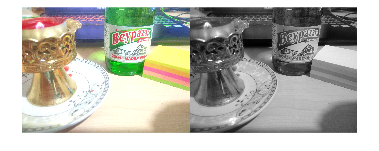

% RENK UZAYI DÖNÜŞÜMLERİ
bey = imread('Beypazari.jpg');
gray = rgb2gray(bey);
hsv = rgb2hsv(bey); 
% Dönüşümleri yaptım
hsv(:,:,3)=hsv(:,:,3)+0.3;
% Parlaklığı keyfi arttırdım
rgb = hsv2rgb(hsv);
imshowpair(rgb,gray,'montage');

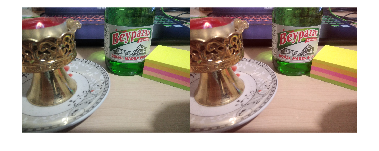

pazar = imread('Beypazari.jpg');
bey=pazar*0;    
% resmin 3 renki boş bir kopyasını oluşturdum
bey(:,:,1)=pazar(:,:,1)+255/10;
% %10 kırmızı ekledim
bey(:,:,2)=pazar(:,:,2);
bey(:,:,3)=pazar(:,:,3);
% diğer renkleri de ekledim
imshowpair(pazar,bey,'montage');

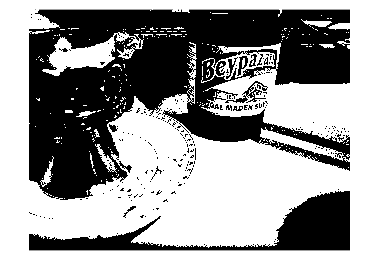

[a,map] = imread('Beypazari.gif');
gray = ind2gray(a,map);
% imgeyi grey yaptım
% imshow(gray);
level = graythresh(gray);
% otsu metodu uyguladım
imshow(im2bw(gray,level));

% imgeleri siyah beyaz yapıp birliştirdim

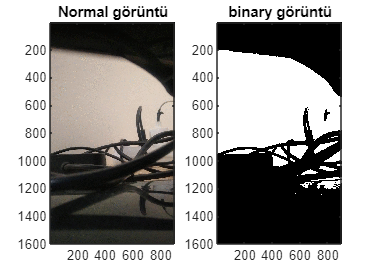

[a,map] = imread('Kablo.gif');
gray = ind2gray(a,map);
% imgeyi grey yaptım
% imshow(gray);
level = graythresh(gray);
% otsu metodu uyguladım
% imshow(im2bw(gray,level));
% imgeleri siyah beyaz yapıp birliştirdim
% imshowpair([a,map],im2bw(gray,level),'montage');
subplot(1,2,1),subimage(a,map);
title('Normal görüntü')
subplot(1,2,2),subimage(im2bw(gray,level));
title('binary görüntü');

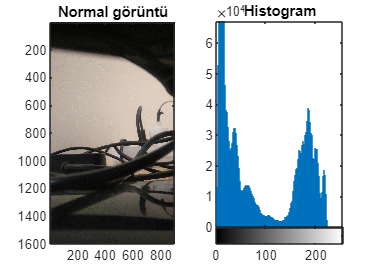

Kablo = imread("Kablo.jpeg");
imhist(Kablo);
title('Histogram')